Code designed to extract differential movement signal from avi webcam video.

v = VideoReader('M9_contraLong2_monitoring.avi');
diffSignal = zeros(v.NumFrames,1);
frame = readFrame(v);
ROI = ROIselect(frame); %Binary mask
npixelROI = sum(sum(ROI)); %no. of pixels in ROI
for i = 1:v.NumFrames
    frame = read(v,i);
    frame = double(rgb2gray(frame)); %Convert to proper gray scale format
    if i == 1
        lastFrame = frame;
    end
    diffFrame = abs(frame-lastFrame);
    diffSignal(i) = sum(sum(diffFrame.*ROI))/npixelROI; %mean diff signal in ROI
    lastFrame = frame;
end

Extract images to show example of movement

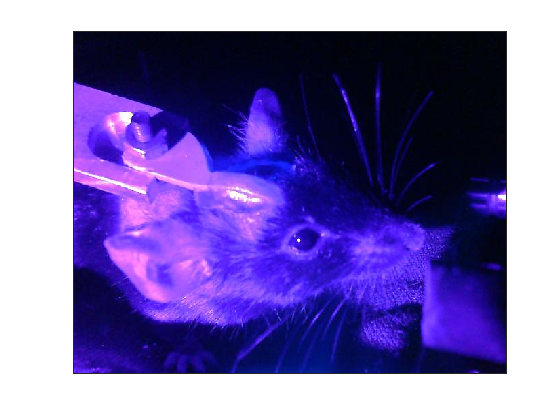

imagesInd = [7296 7297 9325];
frame1 = read(v,imagesInd(1));
frame2 = read(v,imagesInd(2));
frame3 = read(v,imagesInd(3));
figure('Color',[1 1 1]);
image(frame1);
xticks([]);
yticks([]);

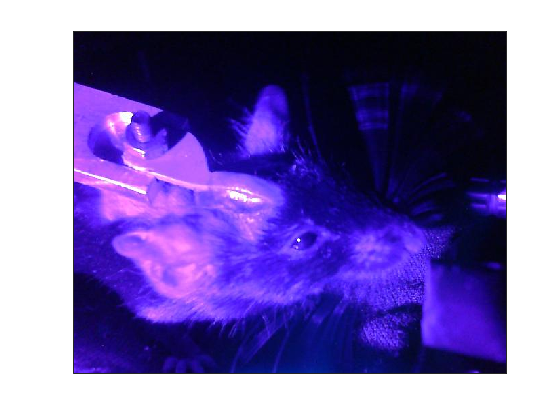

figure('Color',[1 1 1]);
image(frame2);
xticks([]);
yticks([]);

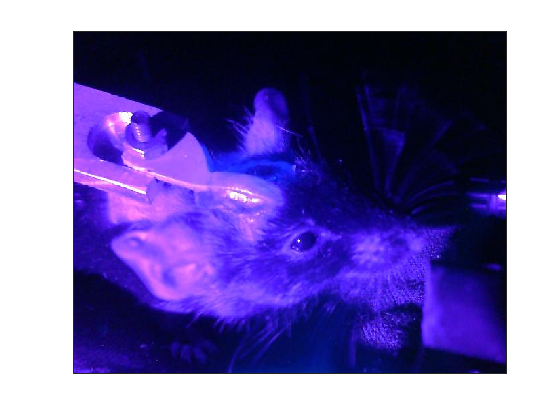

figure('Color',[1 1 1]);
image(frame3);
xticks([]);
yticks([]);

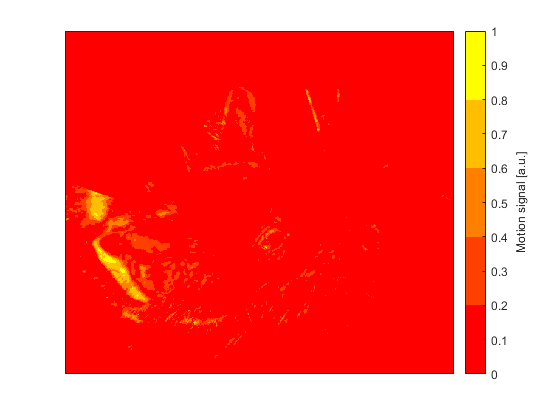

c =   ColorBar (Motion signal [a.u.]) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8167]
       Units: 'normalized'

  Show all properties


%Diff signal between images
frame1 = double(rgb2gray(frame1));
frame2 = double(rgb2gray(frame2));
frame3 = double(rgb2gray(frame3));
figure('Color',[1 1 1]);
imagesc(abs(frame2-frame1)./max(max(abs(frame2-frame1))));
xticks([]);
yticks([]);
c = colorbar;
c.Label.String = 'Motion signal [a.u.]'

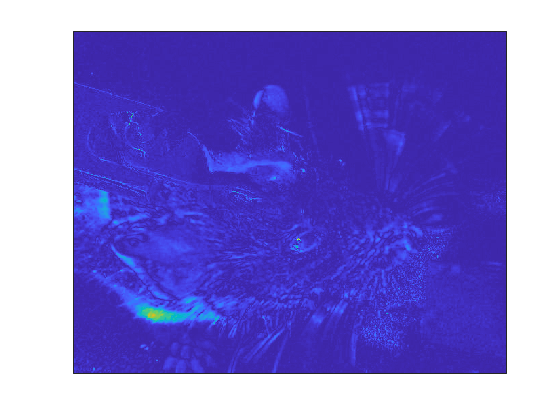

c.Label.FontWeight = 'bold'
figure('Color',[1 1 1]);
imagesc(abs(frame3-frame2)./max(max(abs(frame3-frame2))));
xticks([]);
yticks([]);